**Generation of DSBSC signal**

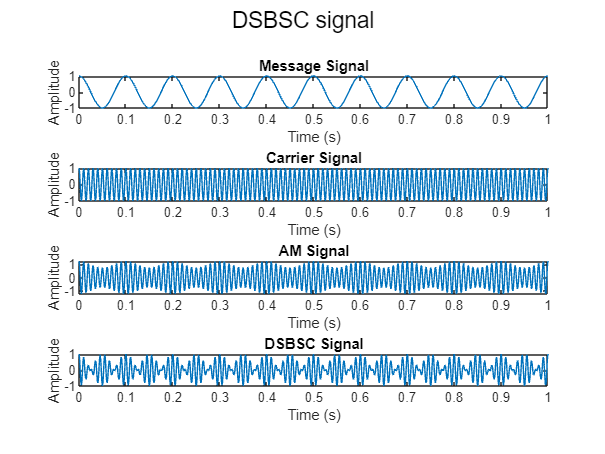

%define parameters
fc=100;
fs=10*fc;
t=0:1/fs:1;
fm=10;
am=1;
ac=1;
u=0.25;   

%message signal
m=am*cos(2*pi*fm*t);

%carrier signal
c=ac*cos(2*pi*fc*t);

%modulation
s=(1+(u*m)).*c;

%dsbsc signal
d=m.*c;

%plot signals
figure;
subplot(4,1,1);
plot(t, m);
title('Message Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,2);
plot(t, c);
title('Carrier Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,3);
plot(t, s);
title('AM Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(4,1,4);
plot(t, d);
title('DSBSC Signal');
xlabel('Time (s)');
ylabel('Amplitude');

%display the plot
sgtitle('DSBSC signal');